# Pool fire modelization example 

In this example, we will introduce the several functions implemented for jet fire modelization. 

clear
clc

## 1. Parameters initialization : 

%% Initiation : 
Ps = 10 ; % initial pressure of vessel - MPa
uw = 5 ; % wind speed - m/s 
Cp = 1.52 ; %  specific heat capacity Cp of flamable substance kj/kg/k
Ta = 288 ; % ambiant temperatrue - K
mass_flow = 30 ;  % of fuel gas kg/s 
Pa = 0.1 ; % ambiant pressure in MPa
molecular_weight = 0.0186 ; % of the fuel  gas, kg/mol
molecular_weight_air = 0.029 ; % kg/mol
teta_jv = 85 ; % [0-90] the angle between the axis of the hole and the horizontal axis in the direction of the wind (in degrees) 
air_density = 1.225 ; % desntity of ambiant air - kg/m3 
Ts = 288 ; % initial temperatuer of vessel - K
d0 = 1 ; % hole diameter in [mm]
combustion_heat = 38000; % of flamable substance - KJ/Kg
Pow  = 2320 ; % saturation vapour pressure in the air in Pa
RH  = 0.7 ; % humidity ratio in [0-1]

**Resolution of computations for heatflux & thermal effects  :** A higher value => smaller step => slower execution 

Indicative values :  125  - 250 - 500 

Resolution = 125 ; % 125 250 500 

**Body coverage : ** Impact of clothes on thermal radiation :  

0.94  : summer clothes  - small mitigation 

0.14 : winter clothes - mitigation 

1 : ignore clothes impact

Fk = 1 ;  


**Safety factor : **over-estimate heatflux value 

safety_factor = 1 ; % 1 or 2 

Compute  specific heat ratio : 

R = 8.314 ; 
gamma = Cp*10^3  / (Cp*10^3 - R/molecular_weight ) ; 

## 2. Computations 

Computing temperature, pressure & velocity of flow at orifice : 

in **K, Pa, m/s**

[To,Po,uo] = exit_conditions_computation(Ps,Ts,Pa,gamma,molecular_weight,mass_flow,d0) 

To = 74.3445

Po = 5.2551

uo = 1.1515e+05

Computing mach number of the flow based on its nature : supersonic or subsonic 

 a = Ps / Pa ; 
 b = ( (gamma+1)/2 )^(gamma/(gamma-1)); 
 if (a>=b)
    mach = supersonic_mach_number_computation(Po,Pa,gamma)                      
 else
    mach = subsonic_mach_number_computation(uo,gamma)      
 end 

mach = 3.7145

Velocity of the flammable fuel gases in the expanding jet in** m/s**

uj = flow_velocity_computation(mach , gamma , To, molecular_weight) 

uj = 805.9236

Computing geometric properties of the jet : 

Ds : the diameter of a hypothetical nozzle through which flows fuel inmeters 

Lb : length of the flame  in meters 

Lbo : in meters 

alpha : in degrees- angle between the axis of the hole and the axis of the flame

b : lift-off from ground (meters)

phi : angle between orifice axis &  center of frustum tip - degrees 

Rl : length of the frustum - in meters 

W1 :  frustum base width - m   -  W2 :   frustum tip width - m 

A :  surface area of frustum including end discs, m² 

[Ds,Lb,Lbo,alpha,b,phi,Rl,W1,W2,A] = jetfire_goemetric_properties_computation(molecular_weight_air,mass_flow,air_density,uj,uw,teta_jv,molecular_weight,To,Ta)

Ds = 0.1967

Lb = 34.4204

Lbo = 59.7589

alpha = 10.6299

b = 6.2364

phi = 8.7146

Rl = 28.2718

W1 = 2.7587

W2 = 10.0436

A = 658.4419

Surface emmitting power in kW/m²

SEP = SEP_computation(uj,combustion_heat, mass_flow , A );

**Compute heat flux for various distances from flame center **

**heat_flux_batch1D :  Heatflux array in kW/m²  **

**R_1D : Distances in meters **

[R_1D,heat_flux_batch1D] = batch_heat_flux_computation_1D(SEP,Rl,Resolution, b,teta_jv, alpha, Pow,RH ,W1,W2 );
 if(safety_factor > 1)
    heat_flux_batch1D = safety_factor.*heat_flux_batch1D ;
 end
 
 
 %%% curve fitting 
 [heatflux_from_distance_fit, gof] = fit_get_heatflux(R_1D, heat_flux_batch1D);

 interpolation_str ={formula(heatflux_from_distance_fit),' parameters resp : ',num2str(coeffvalues(heatflux_from_distance_fit)),'R^2 = ',gof.rsquare };
 [distance_from_heatflux_fit] = fit_get_distance(heat_flux_batch1D, R_1D);

**Compute probabilities of injury for various distances using probit functions  : **

Level 1 skin burns - Level 2 - Death 

[P_level1_1d_batch,P_level2_1d_batch, P_level3_1d_batch ] = batch_ppl_effect_computation_1D(Fk,R_1D,  W1,W2 , distance_from_heatflux_fit  ,heatflux_from_distance_fit); 

## 3. Ploting results 

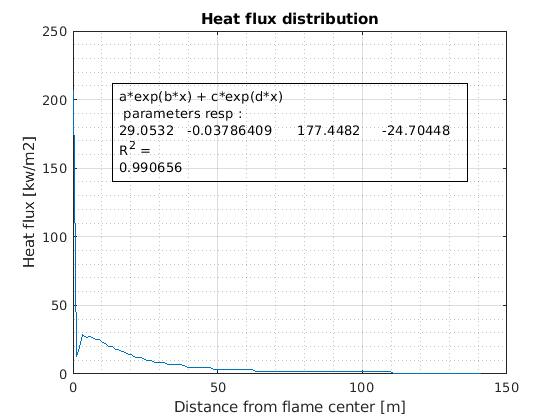

plot1Dheatflux(R_1D,heat_flux_batch1D,interpolation_str)

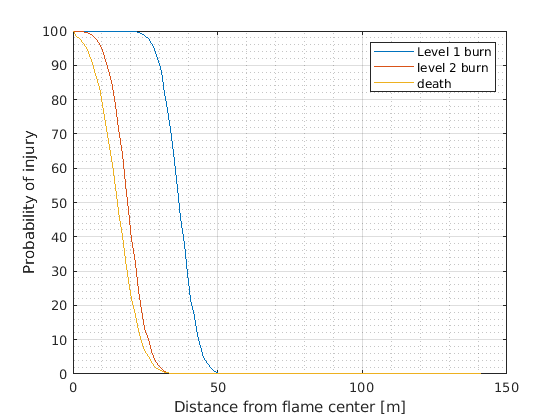

pause(1);
plot_ppl_effects(R_1D,P_level1_1d_batch,P_level2_1d_batch, P_level3_1d_batch)

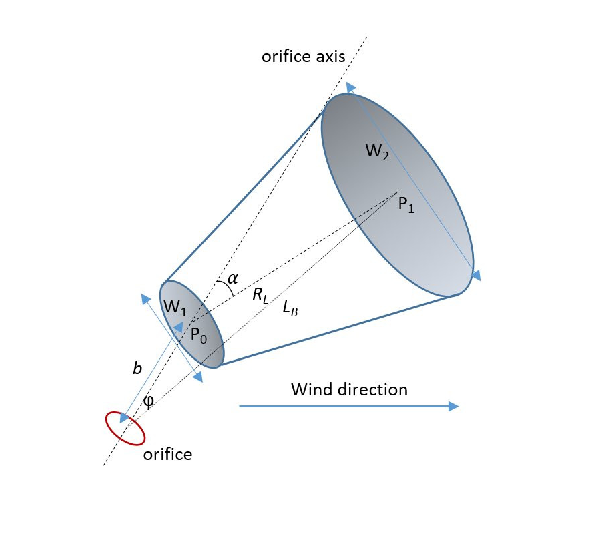

pause(1);

uf = uifigure('Name','Flame Geometry');
uf.Position(3:4) = [375 360];
uit = uitable(uf);
uit.RowName = {'Area [m²]','Flame length / L_b [m]','Frustum length / R_l [m]','Lift off / b [m] ','W1 [m]','W2','nozzle diameter /Ds [m]','α [°]','φ [°]'};
uit.ColumnName = {'Values'};
data_array = [A;Lb;Rl;b;W1;W2;Ds;alpha;phi];
uit.Data = data_array;

pause(2);
f4 = figure ;
I = imread('Jet-fire-solid-flame-model_W640.jpg');
x = imshow(I); 


Sim_array = [To ; Po ; uo ; uj ; mach];
fx = uifigure('Name','Overview');
fx.Position(3:4) = [400 400]; 
uit2 = uitable(fx);
uit2.Data = Sim_array;
uit2.ColumnName = {'Value'};
uit2.RowName = {'Temp at orifice[k] ' , 'Pressure at orifice[MPa]' , 'Jet velocity orifice[m/s]','Expanding jet velocity[m/s]','Jet mach number'};